# **NonLinear beam-UQlink with ABAQUS**

## **Three part: Nonlinear_beam.mlx  NonLinear_beam.inp.tpl, ReadOutput.m**

**Nonlinear_beam.mlx: main document, wrapper with abaqus and uqlab, probabilistic sampling, running the FE, post process the FE output**

**NonLinear_beam.inp.tpl: template file for FE running, argument format： <X00001>, <X00002>,...**

**ReadOutput.m: read output from .dat file and save FE results to file in case collaspse during running**

## **1 - INITIALIZE UQLAB**

%clearvars;clear all;clc
rng(1,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - Forward model (wrapper with ABAQUS)

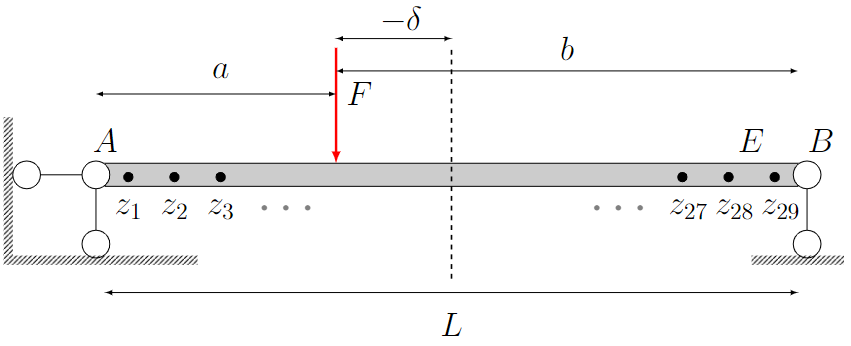

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        L = 30; % beam length (m)

        
$$\delta \;=0;%\;\textrm{loading}\;\textrm{postion}\;\left(m\right)$$


**Computational model:**

Wrapper with ABAQUS, no analytical solution


$$\vec{\theta} = [E,F,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion, *F *is the loading force

$\vec{z} $is the different measurement points along the beam;

% Model type:
ModelOpts.Type = 'UQLink';
ModelOpts.Name = 'NonLinear_beam';
% abaqus ommand line that will be run on the shell:
ModelOpts.Command = 'abaqus -job NonLinear_beam interactive';
% Provide the template file
ModelOpts.Template = 'NonLinear_beam.inp.tpl';
% from the code output file:
ModelOpts.Output.FileName = 'NonLinear_beam.dat';
ModelOpts.Output.Parser = 'ReadOutput';
% Execution path (where Abaqus will be run):
ModelOpts.ExecutionPath = fullfile(pwd()) ;
% Specify the format of the variables written in the Abaqus input file:
ModelOpts.Format = {'%1.8f'};
% Set the display to quiet:
ModelOpts.Display = 'quiet';
% Create the UQLink wrapper:
myUQLinkModel = uq_createModel(ModelOpts);


## 3 - PROBABILISTIC INPUT MODEL

% Elastic modulus
InputOpts.Marginals(1).Name = 'E'; 
InputOpts.Marginals(1).Type = 'Uniform';
InputOpts.Marginals(1).Parameters = [100e9 400e9]; % units: Pa

%loading Force
InputOpts.Marginals(2).Name = 'F'; 
InputOpts.Marginals(2).Type = 'Uniform';
InputOpts.Marginals(2).Parameters = [-3e7 -1e7]; % units: N

% Create the INPUT object
myInput = uq_createInput(InputOpts);

## 4 Sampling and runing

%sample from input space using LHS
N_FE_RUN = 1225;
%X_Sample = uq_getSample(N_FE_RUN,'LHS');


%run the FE models
Y = uq_evalModel(myUQLinkModel,X_Sample);

NonLinear_beam000001 is finished!
NonLinear_beam000002 is finished!
NonLinear_beam000003 is finished!
NonLinear_beam000004 is finished!
NonLinear_beam000005 is finished!
NonLinear_beam000006 is finished!
NonLinear_beam000007 is finished!
NonLinear_beam000008 is finished!
NonLinear_beam000009 is finished!
NonLinear_beam000010 is finished!
NonLinear_beam000011 is finished!
NonLinear_beam000012 is finished!
NonLinear_beam000013 is finished!
NonLinear_beam000014 is finished!
NonLinear_beam000015 is finished!
NonLinear_beam000016 is finished!
NonLinear_beam000017 is finished!
NonLinear_beam000018 is finished!
NonLinear_beam000019 is finished!
NonLinear_beam000020 is finished!
NonLinear_beam000021 is finished!
NonLinear_beam000022 is finished!
NonLinear_beam000023 is finished!
NonLinear_beam000024 is finished!
NonLinear_beam000025 is finished!
NonLinear_beam000026 is finished!
NonLinear_beam000027 is finished!
NonLinear_beam000028 is finished!
NonLinear_beam000029 is finished!
NonLinear_beam

## 5 Post process output

extract the data from .mat file from FE_Results file

Y_Sum = {};
% define the file .mat file stored
subfolder = 'FE_Result';
%loop to extract data from XXX.mat file
for k = 1: size(X_Sample,1)
    filename  = ['NonLinear_beam', sprintf('%06d', k),'.mat'];
    load([fullfile(subfolder,filename)]);
    Y_Sum{k} = findata;
end

%get total increment number in a FE run
N_incre_total = size(findata,2);
%get the measurement point along the beam
N_Deflection = size(findata,1);
%get the total FE run
N_FE_RUN = size(Y_Sum,2);

%loop to extract the FE deflection
N_stage = 10;
increment = linspace(1,N_incre_total,N_stage);
increment = ceil(increment);

%initial Alldata value
FE_Sum = cell(1,N_stage);

%initial stage number
k = 0;
for j = increment
    k = k+1;
    stageData = [];
    for i= 1:N_FE_RUN
        Y_i = Y_Sum{i};
        tempStage = Y_i(:,j);
        stageData = [stageData tempStage ];
    end
    stageData = stageData';
    if k<= N_stage
        FE_Sum{k}= stageData; 
    end
end

save all the FE result

save FE_Output_Results 